# Figure 2E left

**Load Data**

clear
[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
dataDir = '..\..\FINAL DATA files';
load([dataDir filesep 'A062_data.mat'],'S','settings','allIF');
conditions = settings.conditions

conditions = 18×5 cell array
    {'siCtrl DOX'    }    {[2]}    {[  2 3 4]}    {[1]}    {[0]}
    {'siDONSON DOX'  }    {[3]}    {[  2 3 4]}    {[1]}    {[0]}
    {'siCCNA2 DOX'   }    {[4]}    {[  2 3 4]}    {[1]}    {[0]}
    {'siCCNE1/2 DOX' }    {[5]}    {[  2 3 4]}    {[1]}    {[0]}
    {'siCCNB1 DOX'   }    {[6]}    {[  2 3 4]}    {[1]}    {[0]}
    {'siTICRR DOX'   }    {[7]}    {[  2 3 4]}    {[1]}    {[0]}
    {'siCtrl DMSO'   }    {[2]}    {[5 6 7 8]}    {[1]}    {[0]}
    {'siDONSON DMSO' }    {[3]}    {[5 6 7 8]}    {[1]}    {[0]}
    {'siCCNA2 DMSO'  }    {[4]}    {[5 6 7 8]}    {[1]}    {[0]}
    {'siCCNE1/2 DMSO'}    {[5]}    {[5 6 7 8]}    {[1]}    {[0]}
    {'siCCNB1 DMSO'  }    {[6]}    {[5 6 7 8]}    {[1]}    {[0]}
    {'siTICRR DMSO'  }    {[7]}    {[5 6 7 8]}    {[1]}    {[0]}
    {'siCtrl TAK'    }    {[2]}    {[9 10 11]}    {[1]}    {[0]}
    {'siDONSON TAK'  }    {[3]}    {[9 10 11]}    {[1]}    {[0]}
    {'siCCNA2 TAK'   }    {[4]}    {[9 10 11]}    {[1]}    {[


framesPerHr = 60/12;
frameDrugAdded = 13;
frameEdU = 0;
timeStart = 0;

folding =5;

numFrames = size(S(1).area,2);
xFrames = 1:numFrames;
xTime = (xFrames-1)./framesPerHr;

times = arrayfun(@(x)(numFrames - x.POI)/framesPerHr,S,'UniformOutput',false);
[S.POI_time] = times{:};

for i = 1:length(S)
    S(i).POI_realtime = S(i).POI/framesPerHr;
    S(i).POI_drug_time = (frameDrugAdded - S(i).POI)/framesPerHr;
end

**Gate cells**

xthresh =1.1e6; %x value of peak
xrange = linspace(2.4e6,1000); %row vector of 1000 points between x and y (all the data)
for i = 1:length(allIF)
    xdata = allIF(i).DNA;
    [f, xi] = ksdensity(xdata,xrange); %probility density plot of values from all xdata to xrange - max x of first peak
    xi_trunc = xi(xi<xthresh); %xi_trunc = all xdata <x thresh (peak of first peak)
    f_trunc = f(xi<xthresh); % f_trunc = probability density estimate for all xdata <x tresh
    [~, maxi] = max(f_trunc); %maxi = index of peak
    N_peak = xi_trunc(maxi); %peak is max of (all xdata<x thresh) which is at index maxi
    S(i).DNA_peak = N_peak;
end


**Normalized**

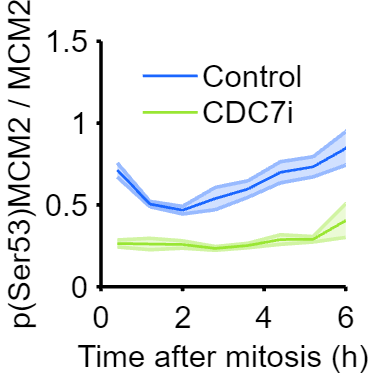

ans = 8001

ans = 2716

conds=[7 13] ;
poi_list = [1];
offset=0;

colors = [.1 .4 1; .6 .9 .2;.4 .1 .5; 0 .7 1];
   figure('Units', 'Inches', 'Position', [0, 0, 4, 4])
   hold on
gateVals = {{},{},{},{},{},{},{},{}};
rangeVals = {{[]},{[]},{[]},{[]},{[]},{[]},{[]},{[]}};
name = {'mitosis'};
edges = (0:(4/framesPerHr):24);
lims = {[0 6],[0 10],[0 6]};
for p = 1:length(poi_list)
    poiAligned=poi_list(p);
   
   
    
    for i=1:length(conds)
        
        ind= ~isnan(S(conds(i)).POI_time(:,poiAligned));
         
           sum(ind)
        xdata = S(conds(i)).POI_time(ind,poiAligned);
        ydata = [];
        ydata(:, 1) = (S(conds(i)).iRFP1(ind));
        ydata(:, 2) = (S(conds(i)).RFP1(ind));
        ydata(:, 3) = (S(conds(i)).YFP1(ind));
        ydata(:,4) = ydata(:,1)./ydata(:,3);

        [binData, edges] = bin_xy(xdata, ydata, {'mean','median','std'},...
            'Edges',edges);
        midpoints = edges + (edges(2) -edges(1))/2;
        midpoints = midpoints(1:end-1);

        bin_gate = binData(4).numCells > 10;


        shadedErrorBar(midpoints(bin_gate), binData(4).mean(bin_gate), 2*binData(4).std(bin_gate)./sqrt(binData(4).numCells(bin_gate)),'lineProps',{'Color',colors(i,:),'LineWidth',1.5})
           xlabel(['Time after ' name{p} ' (h)']);
        ylabel('p(Ser53)MCM2 / MCM2');
        xlim(lims{p});
        xticks(0:2:6)
        ylim([0 1.5])
        axis square
        hold on
        set(gca,'linewidth',2,'fontsize',17)
      
    end
    legend('Control','CDC7i','fontsize',17,'box','off','location','north')
 % print_pdf(['fig_2E_left.pdf'])

end